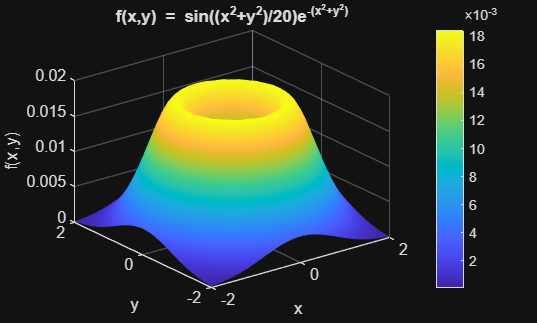

% Name: Augustas
% Surname: Padegimas
% Group: EDIfu-25/2
% Laboratory work: 2
% Variant: 6
% Date: 2026-09-21

% Create x and y values from -2 to 2
x = linspace(-2, 2, 30);
y = linspace(-2, 2, 30);

[X, Y] = meshgrid(x, y);

Z = sin((X.^2 + Y.^2)/20) .* exp(-(X.^2 + Y.^2));

figure;

surf(X, Y, Z);

shading interp;
grid on;

colormap parula;

title('f(x,y) = sin((x^2+y^2)/20)e^{-(x^2+y^2)}');
xlabel('x');
ylabel('y');
zlabel('f(x,y)');

colorbar;

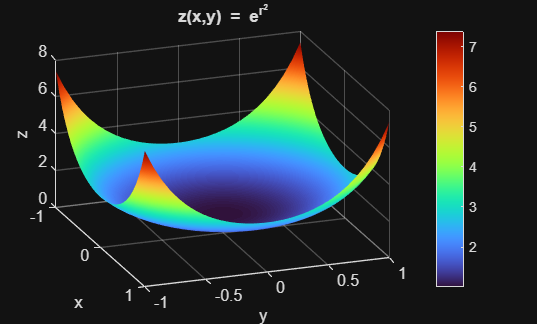


x = linspace(-1, 1, 30);
y = linspace(-1, 1, 30);

[X, Y] = meshgrid(x, y);

r = sqrt(X.^2 + Y.^2);

Z = exp(r.^2);

figure;

surf(X, Y, Z);

shading interp;
grid on;

colormap turbo;

title('z(x,y) = e^{r^2}');
xlabel('x');
ylabel('y');
zlabel('z');

view(70, 30);

colorbar;

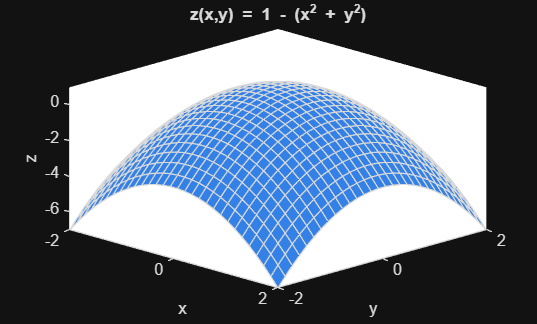


x = linspace(-2, 2, 30);
y = linspace(-2, 2, 30);

[X, Y] = meshgrid(x, y);

Z = 1 - (X.^2 + Y.^2);

figure;

surf(X, Y, Z);

myColor = [0.2 0.5 0.9];

set(gca, 'Color', 'w');
h = findobj(gca, 'Type', 'Surface');
h.FaceColor = myColor;

grid on;

title('z(x,y) = 1 - (x^2 + y^2)');
xlabel('x');
ylabel('y');
zlabel('z');

view(45, 30);